# MATLAB Basics

### `WHAT IS MATLAB`

[`MATLAB®`](https://www.mathworks.com/products/matlab.html)` is a programming platform designed specifically for engineers and scientists. The heart of MATLAB is the MATLAB language, a ``matrix-based language`` allowing the most natural expression of computational mathematics.`

### `DECLARING VARIABLES`

`Declaring varibales in MATLAB does not require any extra keyword (var/int/char/bool... etc.) like many programming languages. Similar to Python you can declare a varibale only using the variable's name. ``No data type specification is required.`

a = 1; 
b = 2.03;
c = 3e8; % 3x10^8
d = 'y';
e = "matlab";
f = true;

### `DATA TYPES`

`All numreric variables in MATLAB are considered of type  '``Double' ``which is a floating point number``. ``You can use the ``class() ``command to check the data-type of a variable.`

class(f)

### **COMMENT**

`To create a single-line comment in MATLAB use the ``"%"`` character. Use ``"%{ --- %}"`` to make multi-line comment.`

% THIS IS A COMMENT
%{
    MULTI
    LINE
    COMMENT
%}

### ARITHMATIC OPERATIONS

`Similar to other programming languages.`

1 + 2
6 - 3
7 * 5
3 / 8
6 ^ 4
mod(10, 3) % MODULUS

### SOME BUILT-IN FUNCTIONS

a = sin(3)
b = cos(4)
c = tan(a)
d = atan(b)
e = 2 * pi
f = sqrt(c)
g = sqrt(b)

### COMPLEX STATEMENTS

 
$$x=\sin \left(\frac{\sqrt{a^2 +b^2 }}{e^{\textrm{ab}} }\right)$$


x = sin((sqrt(a^2 + b^2)) / exp(a * b))

`And when things get too large - Divide and Conquer! For the above example and alternative way might be following.`

numerator = sqrt(a^2 + b^2);
denominator = exp(a * b);
x = sin(numerator / denominator)

# Arrays and Matrices

### All MATLAB VARIABLES ARE ARRAYS!

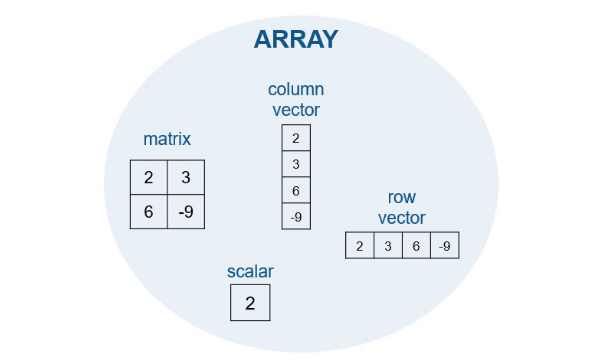

- S`ingle element arrays are called ``Scalars`

- `Multi-element 1D arrays are called ``Vectors`

- `2D arrays are called ``Matrices`

a = 1;
size(a)

### CREATING ARRAYS

`You can create arrays using the '[ ]' symbols in MATLAB. Using a ``comma`` between elements is optional but`` recomended``.`

a = [1, 2, 3, 4, 5]
size(a)

### ROW AND COLUMN VECTORS

`Both row and column vectors are 1D matrices.`

% ROW VECTOR
a = [1, 2, 3, 4]
size(a)

% COLUMN VECTOR
b = [1; 2; 3; 4]
size(b)

### TRANSPOSE

`You can use the " ' " symbol to transpose a vector or a Matrix`

a = [1, 2, 3]
b = a'
c = b'

### CREATING MATRICES

`Combining both row and column vector concept, we can create a matrix`

M = [1, 2, 3; 4, 5, 6; 7, 8, 9]
size(M)

% Transpose Matrix
M'

### INITIALIZING MATRICES

`For better performence a matrix should be initialized before using. There are some built-in functions that you can use to inialize a large matrix.`

### ZEROS

`Creates a matrix with all zero elements.`

% help zeros
a = zeros(3)
b = zeros(1, 3)
zeros(3, 1)

### ONES

`Creates a matrix with all one elements. You can use this to initialize a matrix with any particular number.`

x = ones(2, 3)
y = 4 * ones(4)

### IDENTITY

`In `[`linear algebra`](https://en.wikipedia.org/wiki/Linear_algebra)`, the ``identity matrix`` (sometimes ambiguously called a ``unit matrix``) of size ``n`` is the ``n`` × ``n` [`square matrix`](https://en.wikipedia.org/wiki/Square_matrix)` with ones on the `[`main diagonal`](https://en.wikipedia.org/wiki/Main_diagonal)` and zeros elsewhere`

x = eye(3)
x = 2 * eye(5)

### RANDOM

x = rand(3)
y = randn(3, 4)
z = randi(10, [2, 3])

### MAGIC

`magic(n) returns an n-by-n matrix constructed from the integers 1 through n2 with equal row and column sums. The order n must be a scalar greater than or equal to 3 in order to create a valid magic square.`

x = magic(3)

# The Colon Operator

`The colon operator " : " in MATLAB is used to define a range of values. It is commonly used for array creation, array subscripting anf for loop iteration.`

`Syntax : ``range = start_value : end_value`

`This will create a vector with starting element of the start_value and increamenting by 1 to the end_value.`

a = 1 : 5
b = 4 : 7
c = -3 : -1

### CUSTOM INCREMENT

`x = j : i : k`` creates a regularly-spaced vector x using i as the increment between elements.`

x = 1 : 3 : 10
y = 10 : -2 : 3

### LINSPACE

`Generate linearly spaced vector. linspace(x1,x2) returns a row vector of 100 evenly spaced points between x1 and x2.`

x = linspace(1, 5)
size(x)

y = linspace(1, 10, 3)
size(y)

### MATRIX TO VECTOR

A = [1, 4, 5; 5, 6, 7]
B = A(:)
C = A(:)'

### RESHAPE

`reshape(A,sz) reshapes A using the size vector, sz.`

V = 1 : 9
M = reshape(V, [3, 3])

# Matrix Manipulation

### EXTRACTING ELEMENTS FROM A VECROT OR A MATRIX

`Use the " ( ) " syntax for acessing elements of a vector or a matrix. `

`/////////////////////////////////////////`

`In Matlab Array Index Starts with 1 not 0`

`/////////////////////////////////////////`

V = 1 : 6
M = magic(3)

`Accessing elements of ``Matrix A`

V(4)
V(end)
V(end - 1)

A(5)
A(3, 3)

### EXTRACTING MULTIPLE ELEMENTS

`You can use the colon operator to extract multiple elements from a matrix`

V(2 : 5)
M(5 : 8)

V(1 : 2 : 5)

### EXTRACTING ROW OR COLUMN

`You can also extract a whole row or column of a matrix using the colon operator.`

M
M(2, :)
M(:, end)

`You can also extract multiple rows or columns`

M
M(2:3, :)
M(:, 1:2)

### MATRIX OPERATIONS

A = 10 * rand(3, 3)
B = randi(10, [3, 3])

A + 4
A + [2, 3, 4]

% ADDITION
A + B
A - B

% SCALAR MULTIPLICATION
A + 5 * B

% MULTIPLICATION
A * B
A^2

### ELEMENT-WISE OPERATION

Use " .* " or " ./ " or " .^ " for element wise multiplication, division and power


$$A\;\ldotp *B=\left\lbrack \begin{array}{ccc}
a_{11} b_{11}  & a_{12} b_{12}  & \ldotp \ldotp \\
\ldotp \ldotp  & a_{\textrm{jk}} b_{\textrm{jk}}  & \ldotp \ldotp \\
\ldotp \ldotp  & \ldotp \ldotp  & a_{\textrm{nn}} b_{\textrm{nn}} 
\end{array}\right\rbrack$$



$$A\;\ldotp^{ˆ\;\;} 2=\left\lbrack \begin{array}{ccc}
a_{11}^2  & a_{12}^2  & \ldotp \ldotp \\
\ldotp \ldotp  & \ldotp \ldotp  & a_{\textrm{nn}}^2 
\end{array}\right\rbrack$$


A = eye(3)
B = randn(3)

% INNER PRODUCT
A .* B

A ./ B
A .^ 5

**NOTE : FOR POWER OPERATION ALWAYS USE .^**

### **OTHER OPERATIONS**

`In MATLAB what you can do with scalers is also applicable for vectors and matrices`

V = 1 : 10
sin(V) .^ 2

M = rand(4)
inv(M)

### CONCATENATION

AB = [A, B]

AB = [A; B]

X = [ones(3, 1), A]